MATLAB reads an image using the `imread` command. We'll use an image that ships with MATLAB for demonstrations.

A = imread('peppers.png');
size(A)

ans =    384   512     3


As stated above, the image has three ``layers'' for red, green, and blue. We can deal with each layer as a matrix, or (as below) convert it to a single matrix indicating shades of gray from black (0) to white (255). Then we have to tell MATLAB to represent the entries as floating-point values rather than integers. 

A = rgb2gray(A); % collapse from 3 dimensions to 2
A = double(A);   % convert to floating point
[m,n] = size(A)

m =    384


n =    512


We now have a matrix. To show it as an image, we use the `imshow` command. We can tell it explicitly which values correspond to black and white.

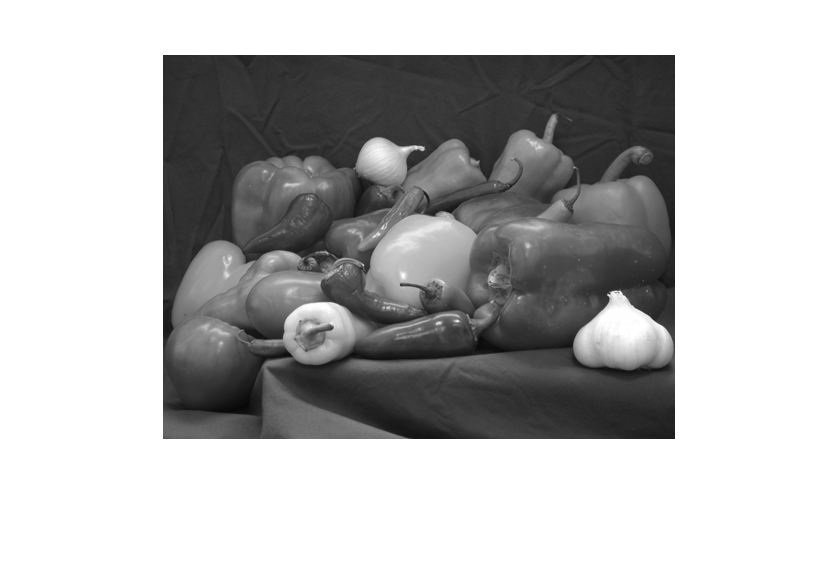

imshow(A,[0 255])